% Load the dataset
data = readtable('Weldingdataset.xlsx');

% Convert Quality column to categorical
data.Quality = categorical(data.Quality);

% Split the data into features and labels
X = table2array(data(:, 1:end-1));  % Features
Y = data.Quality;                   % Labels

% Split the dataset into training and testing sets (80% training, 20% testing)
split = 0.8;
idx = randperm(size(data, 1));
trainIdx = idx(1:round(split * end));
testIdx = idx(round(split * end) + 1:end);
X_train = X(trainIdx, :);
Y_train = Y(trainIdx, :);
X_test = X(testIdx, :);
Y_test = Y(testIdx, :);

% Train the k-NN model
k = 5; % Set the number of neighbors
mdl = fitcknn(X_train, Y_train, 'NumNeighbors', k);

% Predict on the test set
Y_pred = predict(mdl, X_test);

% Evaluate the model
accuracy = sum(Y_pred == Y_test) / numel(Y_test);
disp(['Accuracy: ' num2str(accuracy * 100) '%']);

Accuracy: 12.5%


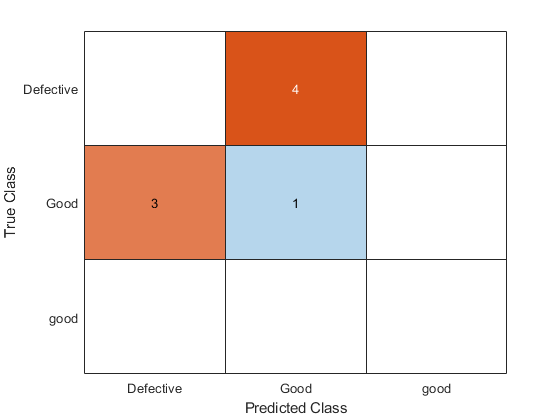

% Plot the confusion matrix
confusionchart(Y_test, Y_pred);